# Compensate for Group Delay

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the signals.

[whaley,fs] = audioread("./data/whalesound.wav");
b = [0.2 0.5 0.2];
whalefilt = filter(b,1,whaley);
n = numel(whaley);
t = (0:n-1)'/fs;

This code plot the group delay.

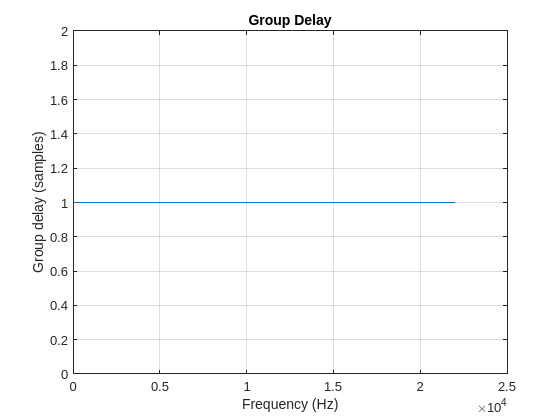

grpdelay(b,1,[],fs)

This code compares the time-domain plots.

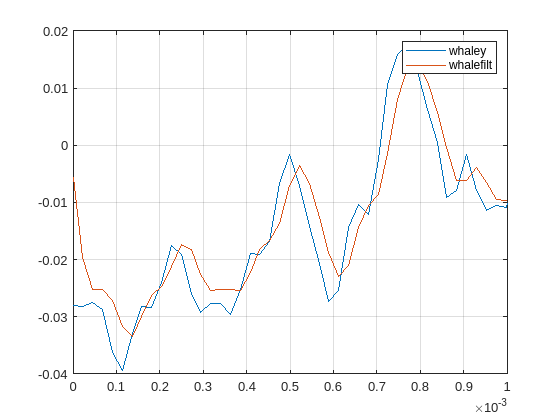

plot(t,whaley)
hold on
grid on
plot(t,whalefilt)
hold off
xlim([0 0.001])
legend(["whaley" "whalefilt"])

## Task 1

When you have a constant group delay, like with this filter, you can compensate by shifting the filtered signal.

You can calculate the number of delayed samples or just save the value that you see in the group delay plot. To calculate it, use an output with the `grpdelay` function:

`gd` `=` `grpdelay``(``b``,``a``)`

Then get the number of delayed samples from the vector. When the filter has constant group delay, every element in the vector is the same so you can extract the first element:

`delay` `=` `gd``(``1``)`

gd = grpdelay(b,1,[],fs)

gd =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


delay = gd(1)

delay = 1

## Task 2

Now you can shift the filtered signal to the left by deleting the appropriate number of samples:

`signal``(``1``:``delay``)` `=` `[]`

whalefilt(1:delay) = [];

## Task 3

To visualize the aligned signal, you need to create a time vector with the same number of elements. You can accomplish this by creating a new time vector, or by removing the appropriate number of elements from the time vector:

`t2 = t1(1:``end``-delay)`

tadj = t(1:end-delay);

## Task 4

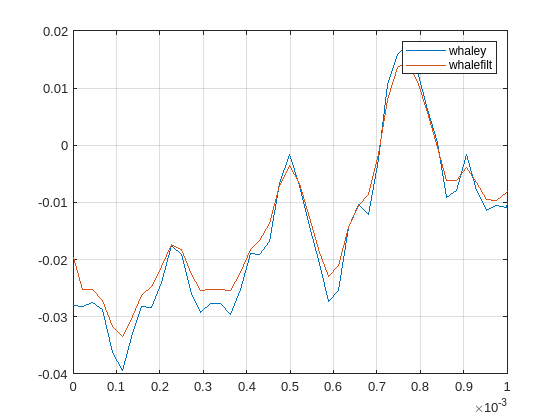

plot(t,whaley)
hold on
grid on
plot(tadj,whalefilt)
hold off
xlim([0 0.001])
legend(["whaley" "whalefilt"])